2.4a 创建函数

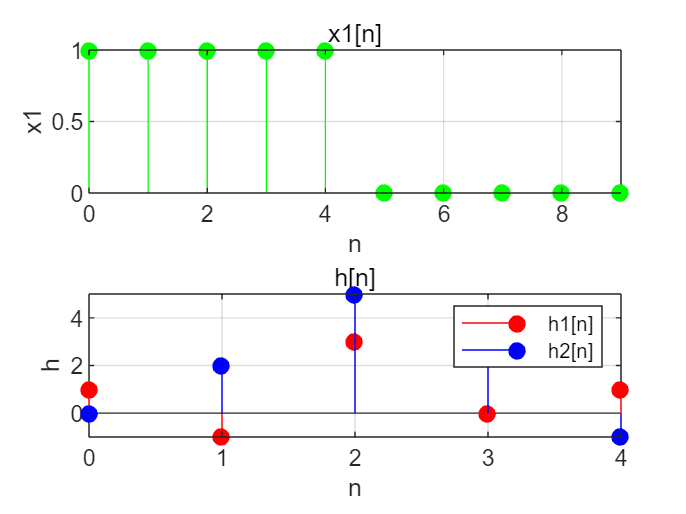

clc,clear,close all;
figure;
x1=[1 1 1 1 1 0 0 0 0 0];
nx=[0 1 2 3 4 5 6 7 8 9];
h1=[1 -1 3 0 1];
h2=[0 2 5 4 -1];
nh1=[0 1 2 3 4];
subplot(2,1,1),stem(nx,x1,'g','filled'),title('x1[n]'),xlabel('n'),ylabel('x1'),grid on,xlim([0 9]);
subplot(2,1,2);
stem(nh1,h1,'r','filled');
hold on;
stem(nh1,h2,'b','filled');
hold off;
legend('h1[n]','h2[n]'),grid on,xlabel('n'),ylabel('h'),title('h[n]');

2.4b x1*h1 h1*x1验证卷积交换律

分析：计算x1*h1、h1*x1，作图比较

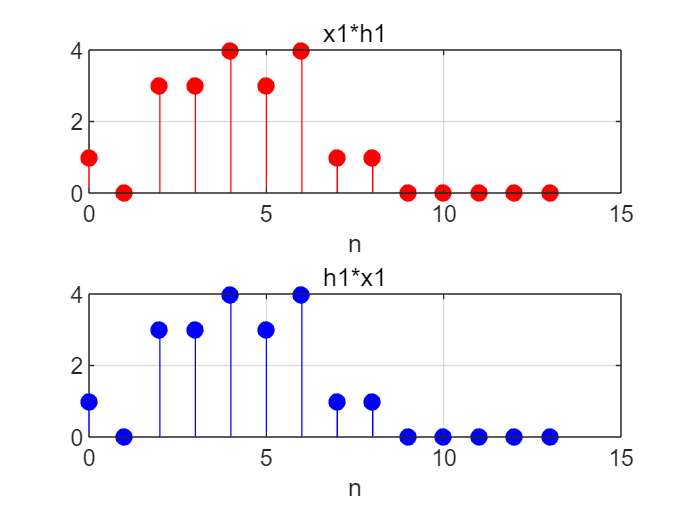

figure;
y1=conv(x1,h1);
ny1=nx(1)+nh1(1):nx(end)+nh1(end);
y2=conv(h1,x1);
ny2=nh1(1)+nx(1):nh1(end)+nx(end);
subplot(2,1,1),stem(ny1,y1,'r','filled'),grid on,xlabel('n'),title('x1*h1');
subplot(2,1,2),stem(ny2,y2,'b','filled'),grid on,xlabel('n'),title('h1*x1');

根据图像比较可得知：两图形相同，x1*h1=h1*x1，故卷积满足交换率。

2.4c 验证x[n] * (h1[n] + h2[n]) = x[n] * h1[n] + x[n] * h2[n]

分析：计算x1*(h1+h2)、x1*h1+x1*h2，作图比较

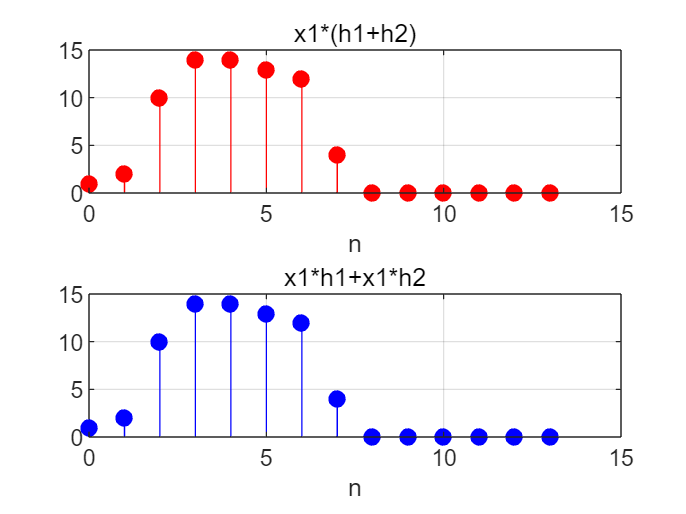

figure;
y3=conv(x1,h1+h2);
ny3=nx(1)+nh1(1):nx(end)+nh1(end);
y4=conv(x1,h1)+conv(x1,h2);
ny4=nx(1)+nh1(1):nx(end)+nh1(end);
subplot(2,1,1),stem(ny3,y3,'r','filled'),grid on,xlabel('n'),title('x1*(h1+h2)');
subplot(2,1,2),stem(ny4,y4,'b','filled'),grid on,xlabel('n'),title('x1*h1+x1*h2');

根据图像比较可得知：两图形相同，x1*(h1+h2)=x1*h1+x1*h2，故卷积满足分配率。

2.4d 验证(x[n] * h1[n]) * h2[n] = x[n] * (h1[n] * h2[n])

分析：计算(x[n] * h1[n]) * h2[n]、x[n] * (h1[n] * h2[n])，作图比较

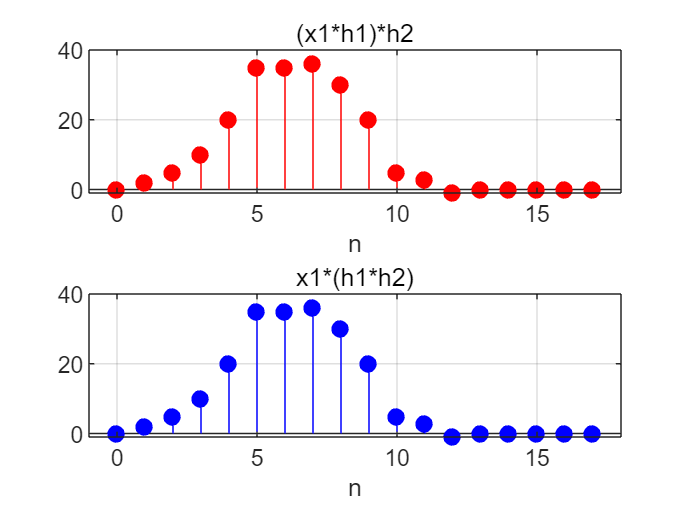

figure;
y5trans=conv(x1,h1);
y5=conv(y5trans,h2);
ny5=nx(1)+nh1(1)*2:nx(end)+nh1(end)*2;
y6trans=conv(h1,h2);
y6=conv(x1,y6trans);
ny6=nx(1)+nh1(1)*2:nx(end)+nh1(end)*2;
subplot(2,1,1),stem(ny5,y5,'r','filled'),grid on,xlabel('n'),title('(x1*h1)*h2'),xlim([-1 18]);
subplot(2,1,2),stem(ny6,y6,'b','filled'),grid on,xlabel('n'),title('x1*(h1*h2)'),xlim([-1 18]);

根据图像比较可得知：两图形相同，(x[n] * h1[n]) * h2[n] = x[n] * (h1[n] * h2[n])，故卷积满足结合率。

2.4e 证明时不变性

分析：按题目要求一步步构造函数ye1[n-n0]、ye2，作图比较

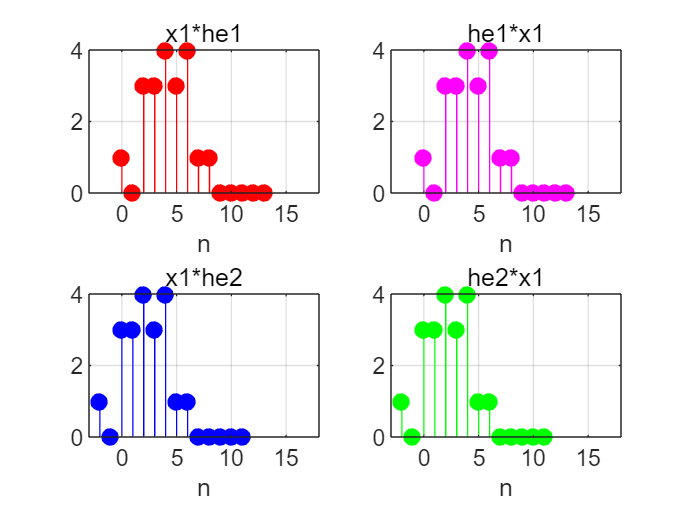

%构造函数
n0=2;
he1=h1;
nhe1=nh1;
he2=h1;
nhe2=nh1-n0;
%验证交换律
ye1=conv(x1,he1);
ye1inverse=conv(he1,x1);
nye1=nx(1)+nhe1(1):nx(end)+nhe1(end);
ye2=conv(x1,he2);
ye2inverse=conv(he2,x1);
nye2=nx(1)+nhe2(1):nx(end)+nhe2(end);
figure;
subplot(2,2,1),stem(nye1,ye1,'r','filled'),grid on,xlabel('n'),title('x1*he1'),xlim([-3 18]);
subplot(2,2,2),stem(nye1,ye1inverse,'m','filled'),grid on,xlabel('n'),title('he1*x1'),xlim([-3 18]);
subplot(2,2,3),stem(nye2,ye2,'b','filled'),grid on,xlabel('n'),title('x1*he2'),xlim([-3 18]);
subplot(2,2,4),stem(nye2,ye2inverse,'g','filled'),grid on,xlabel('n'),title('he2*x1'),xlim([-3 18]);

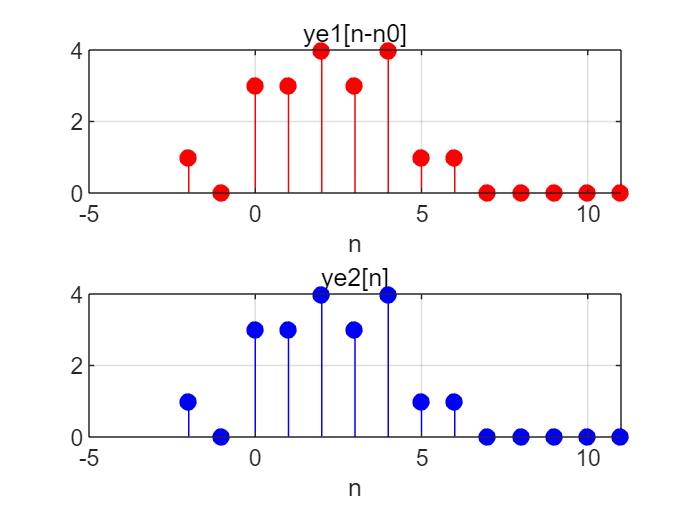

%验证时不变性
figure;
subplot(2,1,1),stem(nye1-n0,ye1,'r','filled'),grid on,xlabel('n'),title('ye1[n-n0]');
subplot(2,1,2),stem(nye2,ye2,'b','filled'),grid on,xlabel('n'),title('ye2[n]');

根据图像比较可得知：两图形相同，ye1[n-n0]=ye2[n]，故函数满足时不变性。

2.4f 判断串联系统1和系统2是否满足卷积的结合律，并解释原因

分析：比较通过两种卷积结合方式算出的yf1,yf2

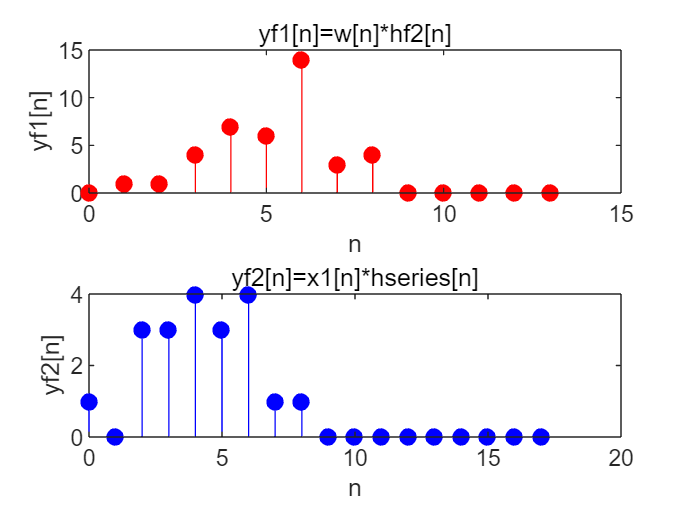

w=nx.*x1;
yf1=conv(w,h1);
nyf1=0:length(nx)+length(nh1)-2;
nhf1=0:4;
hf1=(nhf1==0);
hseries=conv(hf1,h1);
nhseries=0:length(nhf1)+length(nh1)-2;
yf2=conv(x1,hseries);
nyf2=0:length(x1)+length(hseries)-2;
figure;
subplot(2,1,1);
stem(nyf1,yf1,'r','filled');
xlabel('n');
ylabel('yf1[n]');
title('yf1[n]=w[n]*hf2[n]');
subplot(2,1,2);
stem(nyf2,yf2,'b','filled');
xlabel('n');
ylabel('yf2[n]');
title('yf2[n]=x1[n]*hseries[n]');

如图所示，yf1[n]≠yf2[n]，因此这两个系统不满足卷积的结合律。其根本原因是系统1不是LTI系统，其输出信号不能用卷积计算得出，总响应也不能通过两个系统的单位冲激响应的卷积来计算。与(d)问中“卷积满足结合律”的结论并不矛盾。

2.4g 判断并联系统1和系统2是否满足卷积的分配律，并解释原因

分析：比较用分配律的两种计算方式算出的yg1,yg2

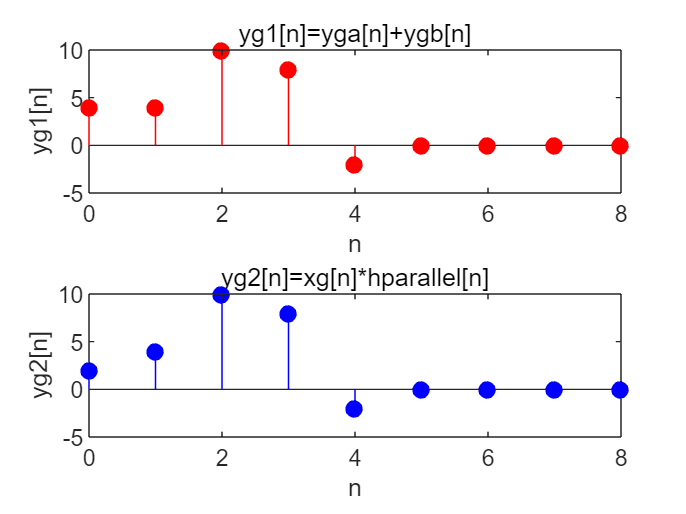

n=0:4;
nh2=0:4;
xg=2.*(n==0);
yga=xg.^2;
ygb=conv(xg,h2);
nygb=0:length(n)+length(nh2)-2;
YGA=[yga 0 0 0 0];%拓展yga长度使其能与ygb相加
yg1=YGA+ygb;
hg1=(n==0);
hparallrel=hg1+h2;
yg2=conv(xg,hparallrel);
nyg2=0:length(n)+length(nh2)-2;
% 绘图
figure;
subplot(2,1,1);
stem(nygb,yg1,'r','filled');
xlabel('n');
ylabel('yg1[n]');
title('yg1[n]=yga[n]+ygb[n]');
subplot(2,1,2);
stem(nyg2,yg2,'b','filled');
xlabel('n');
ylabel('yg2[n]');
title('yg2[n]=xg[n]*hparallel[n]');

 如图所示，yg1[n]≠yg2[n]，因此这两个系统不满足卷积的分配律。其根本原因是系统1不是LTI系统，其输出信号不能用卷积计算得出，总响应也不能通过两个系统的单位冲激响应的和来计算。与(d)问中“卷积满足结合律”的结论并不矛盾。

2.10a 求该系统的单位冲激响应并作图。

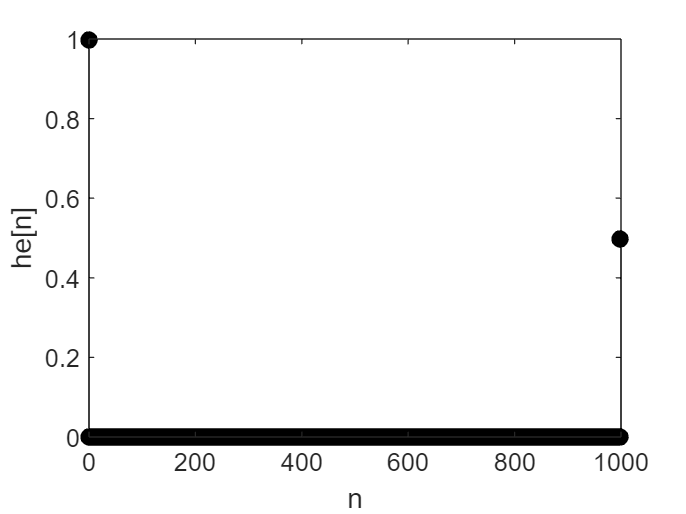

clc,clear,close all;
load lineup.mat;
n=0:1000;
he=(n==0)+0.5*(n==1000);
figure;
stem(n,he,'k','filled');
xlabel('n');
ylabel('he[n]');

2.10b 证明2.22的系统是2.21的逆系统。

分析：要证证明2.22的系统是2.21的逆系统，即证若x[n]输入2.21的系统后得到的y[n]再输入2.22中的系统后得到的z[n]=x[n]。不妨令x[n]=delta[n]。

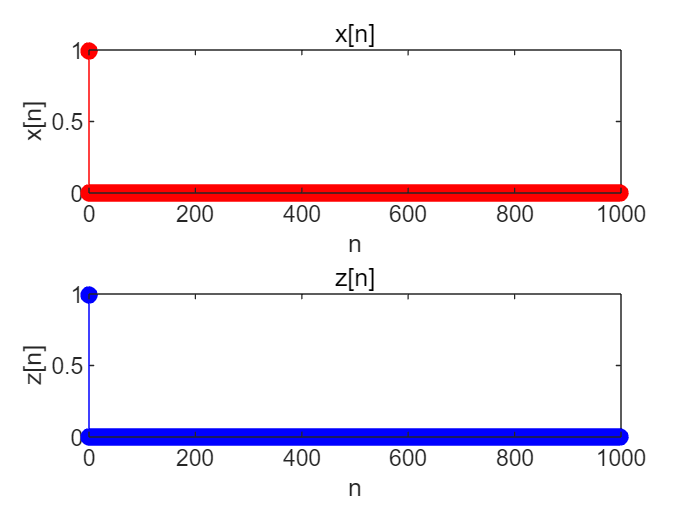

x=(n==0);
a1=1;
b1=[1 zeros(1,999) 0.5];
y1=filter(b1,a1,x);
z=filter(a1,b1,y1);
figure;
subplot(2,1,1);
stem(n,x,'r','filled');
xlabel('n');
ylabel('x[n]');
title('x[n]');
subplot(2,1,2);
stem(n,z,'b','filled');
xlabel('n');
ylabel('z[n]');
title('z[n]');

如图所示，z[n]=x[n]，所以2.22的系统是2.21的逆系统。

2.10c 计算2.22系统的无限冲击响应her的前4001位并作图

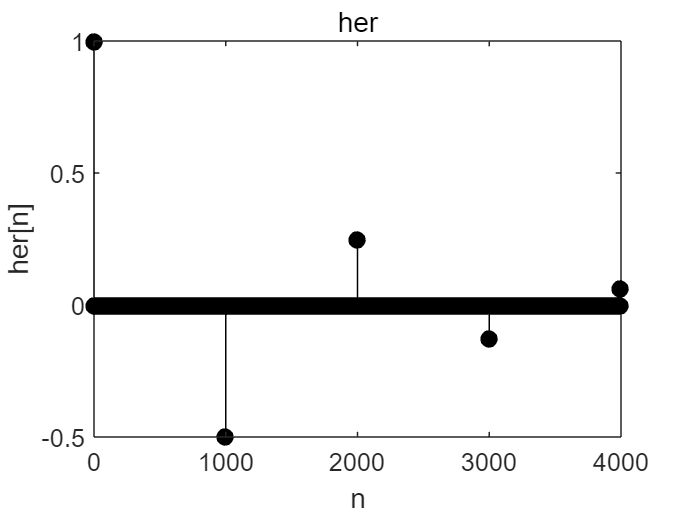

nher=0:4000;
delt=[1, zeros(1,4000)];
her=filter(a1,b1,delt);
figure;
stem(nher,her,'k','filled');
xlabel('n');
ylabel('her[n]');
title('her');

2.10d 利用z=filter(1,ay,y)实现回声消除系统，并作出输出结果的图像，用sound函数读取音频并播放

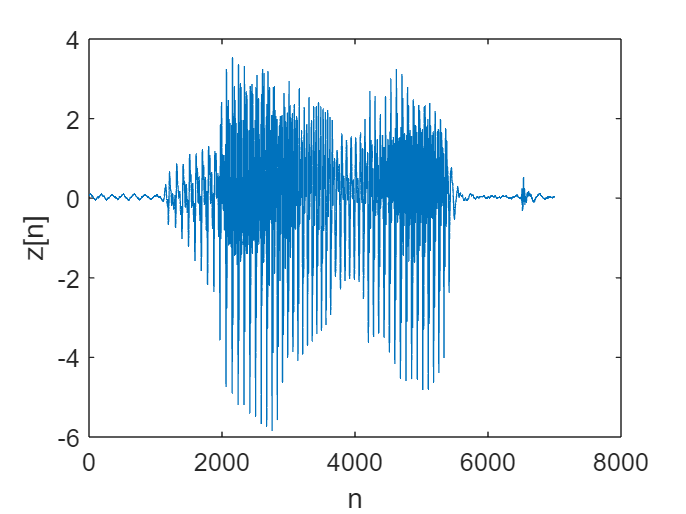

nz=0:6999;
z=filter(1,b1,y);
figure;
plot(nz,z);
xlabel('n');
ylabel('z[n]');

sound(z,8192);

2.10e 级联he和her，并作出输出结果的图像

分析：卷积（he,her），输出hoa图像

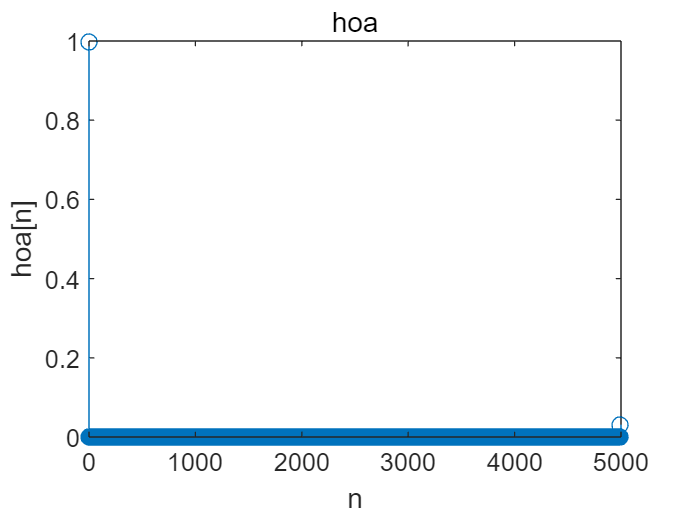

clc,clear,close all;
figure;
nhe=0:1000;
n=0:1000;
he=(n==0)+0.5*(n==1000);
nher=0:4000;
d=[1, zeros(1,4000)];
bx=1;
ay=[1,zeros(1,999),0.5];
her=filter(bx,ay,d);
hoa=conv(he,her);
nhoa=nhe(1)+nher(1):nhe(end)+nher(end);
figure;
stem(nhoa,hoa),title('hoa'),xlabel('n'),ylabel('hoa[n]');

如图所示，hoa图像并非单位冲激信号，由于截断了her，使最后一位数值非零。

2.10f 计算N、α

分析：计算Ryy自相关，找到N。根据N的值，计算最贴合y[n]的系数alpha。

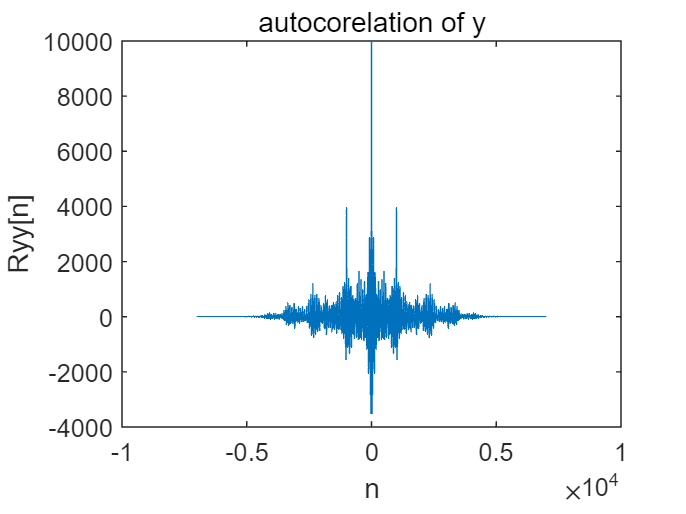

clc,clear,close all;
figure;
%y的自相关
load lineup.mat;
Ryy=conv(y,flipud(y));
nY=7000;
plot([-nY+1:nY-1],Ryy),title('autocorelation of y'),xlabel('n'),ylabel('Ryy[n]');

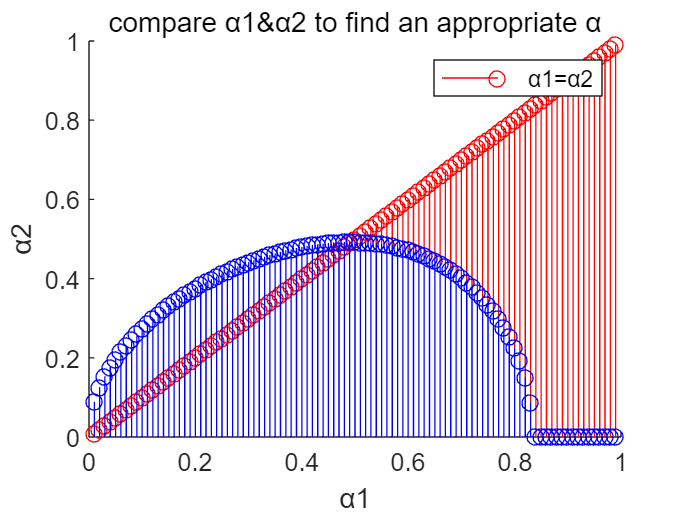

%观察图像，得N=1000
N=1000;
NX=7000;
%尝试α，计算x的自相关
alpha2=[];
i=1;
Ryy0=Ryy(NX);
while i<=99
    b=[1,zeros(1,N-1),0.01*i];
    x=filter(1,b,y);
    Rxx=conv(x,flipud(x));
    Rxx0=Rxx(NX);
    Rxx_N1=Rxx(NX-N);
    Rxx_N2=Rxx(NX+N);
    syms result;
    result=solve(Ryy0 == (1+result*result)*Rxx0,result);
    alpha2=[alpha2 real(result(2))];
    i=i+1;
end
%得到每个尝试值所推导出的真值，根据图像判断合适的α
figure;
t=1:99;
alpha1=t*0.01;
hold on
stem(t*0.01,t*0.01,'r'),legend('α1=α2'),title('compare α1&α2 to find an appropriate α');
stem(alpha1,alpha2,'b'),xlabel('α1'),ylabel('α2');
hold off

根据图像得知，信号为y时，N=1000，α=0.49。

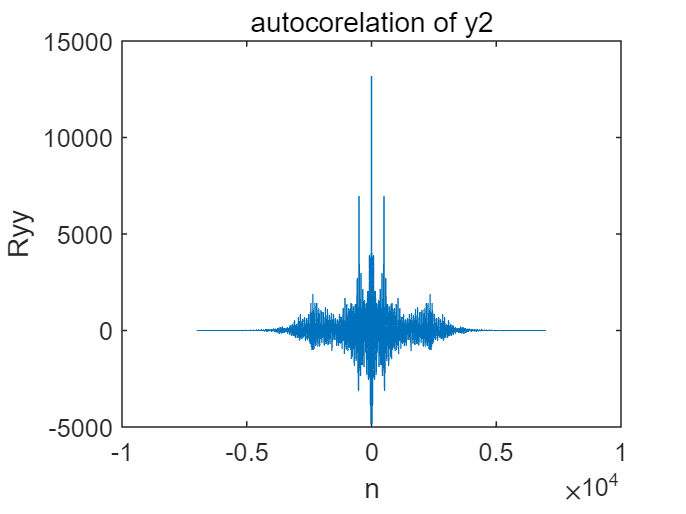

clc,clear,close all;
%y2
figure;
%y的自相关
load lineup.mat;
Ryy=conv(y2,flipud(y2));
nY=7000;
plot([-nY+1:nY-1],Ryy),title('autocorelation of y2'),xlabel('n'),ylabel('Ryy');

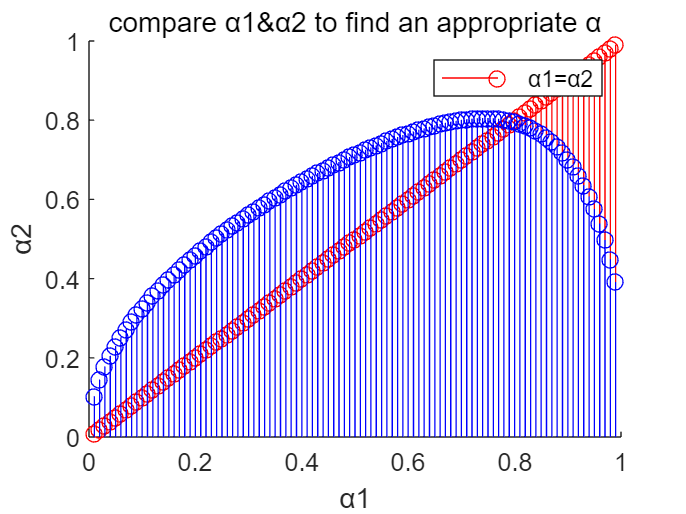

%观察图像，得N=501
N=501;
NX=7000;
%尝试α，计算x的自相关
alpha2=[];
i=1;
Ryy0=Ryy(NX);
while i<=99
    b=[1,zeros(1,N-1),0.01*i];
    x=filter(1,b,y2);
    Rxx=conv(x,flipud(x));
    Rxx0=Rxx(NX);
    Rxx_N1=Rxx(NX-N);
    Rxx_N2=Rxx(NX+N);
    syms result;
    result=solve(Ryy0 == (1+result*result)*Rxx0,result);
    alpha2=[alpha2 real(result(2))];
    i=i+1;
end
%得到每个尝试值所推导出的真值，根据图像判断合适的α
figure;
t=1:99;
alpha1=t*0.01;
hold on
stem(t*0.01,t*0.01,'r'),legend('α1=α2'),title('compare α1&α2 to find an appropriate α');
stem(alpha1,alpha2,'b'),xlabel('α1'),ylabel('α2');
hold off

根据图像得出，信号为y2时，N=501，α=0.80。

clc,clear,close all;
%y3
figure;
%y的自相关
load lineup.mat;
Ryy=conv(y3,flipud(y3));
nY=7000;
plot([-nY+1:nY-1],Ryy),title('autocorelation of y3'),xlabel('n'),ylabel('Ryy');
%观察图像，得N1=751，N2=2252
N1=751;
N2=2252;
figure;
NX=7000;
%尝试α，计算x的自相关
i=1;
Ryy0=Ryy(NX);
Ryy1=Ryy(NX+N1);
count=0;
while i<=99
    j=1;
    while j<=99
        b=[1,zeros(1,N1-1),0.01*i,zeros(1,N2-N1-2),0.01*j];
        x=filter(1,b,y3);
        Rxx=conv(x,flipud(x));
        Rxx0=Rxx(NX);
        Rxx1=Rxx(NX-N1);
        Rxx2=Rxx(NX+N1);
        Rxx3=Rxx(NX-N2);
        Rxx4=Rxx(NX+N2);
        Rxx5=Rxx(NX-N1+N2);
        Rxx6=Rxx(NX+N1-N2);
        Rxx7=Rxx(NX+N1);
        Rxx8=Rxx(NX);
        Rxx9=Rxx(NX+2*N1);
        Rxx10=Rxx(NX+N1-N2);
        Rxx11=Rxx(NX+N1+N2);
        Rxx12=Rxx(NX+N2);
        Rxx13=Rxx(NX+2*N1-N2);
        u=i*0.01;
        v=j*0.01;
        syms a1 a2;
        S=solve([(1+a1^2+a2^2)*Rxx0+a1*Rxx1+a1*Rxx2+a2*Rxx3+a2*Rxx4+a1*a2*Rxx5+a1*a2*Rxx6==Ryy0,(1+a1^2+a2^2)*Rxx7+a1*Rxx8+a1*Rxx9+a2*Rxx10+a2*Rxx11+a1*a2*Rxx12+a1*a2*Rxx13==Ryy1],[a1,a2]);
        a1=real(double(S.a1(1)));
        a2=real(double(S.a2(1)));
        if (a1==u)&&(a2==v)
            disp("α1=");
            disp(u);
            disp("α2=");
            disp(v);
            count=count+1;
        end
        j=j+1;
    end
    i=i+1;
end
count

根据图像得出，信号为y3时，N1=751，N2=2252，α=0.40。